# Lab 3.  Bifurcaciones Saddle-Node, Transcritical, Supercritical Pitchfork & Subcritical Pitchfork (Tridente).

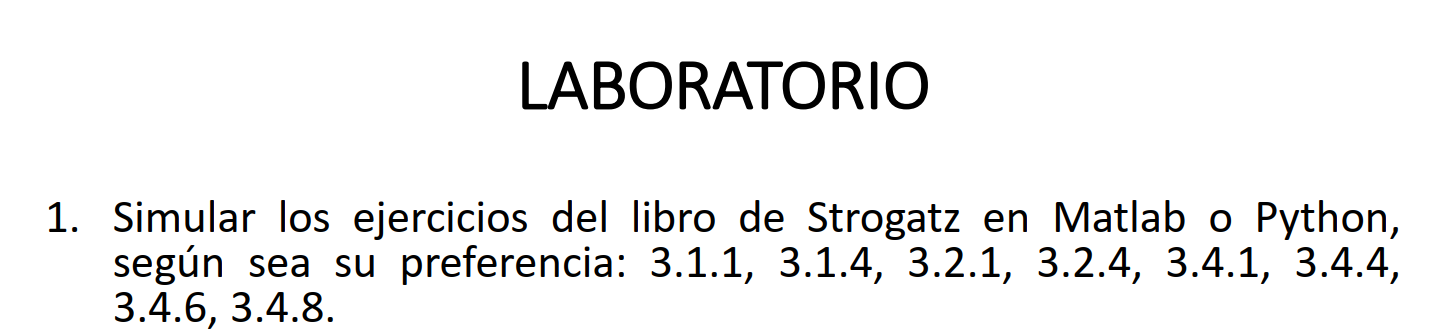

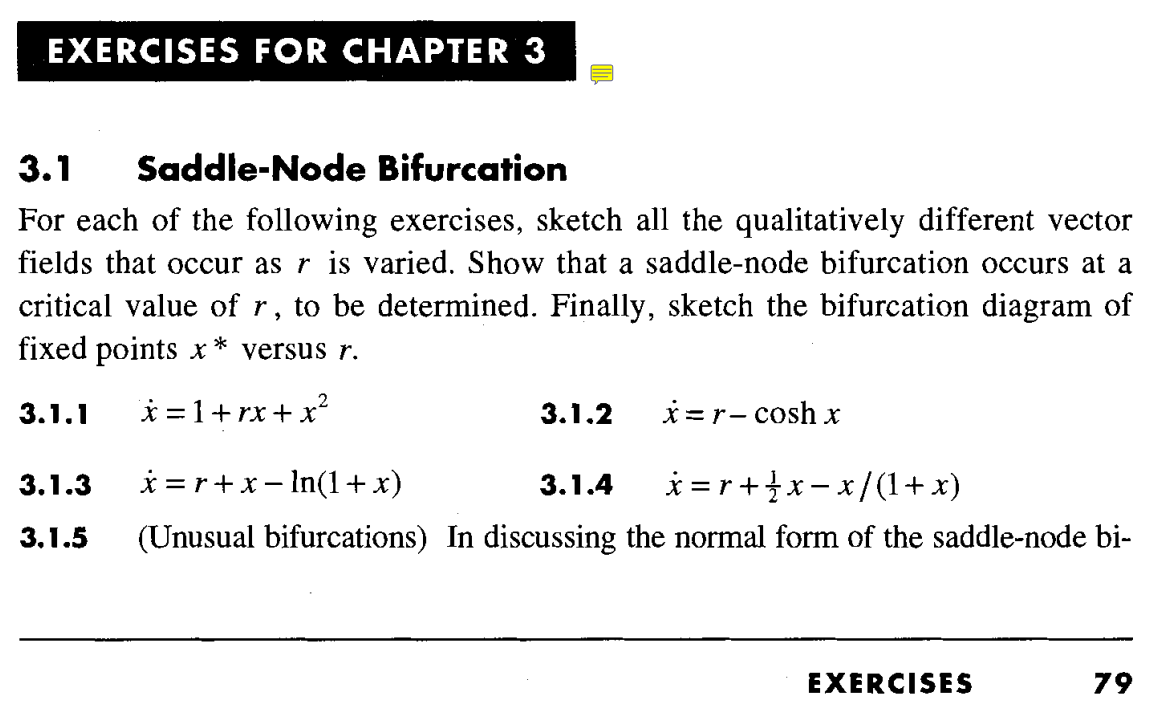

# 3.1.4  Saddle Node Bifurcation.

# Bifurcaciones en sistemas unidimensionales

clc;clear;close all

Para este tipo de bifurcación, se analiza el siguiente sistema:


$$\dot{x} =r+\frac{1}{2}x-\frac{x}{\left(1+x\right)}\ldotp$$


Donde $r$ es el parámetro de bifurcación

syms x r
Fsn = r+1/2*x-x/(1+x) 

$$Fsn = r+\frac{x}{2}-\frac{x}{x+1}$$

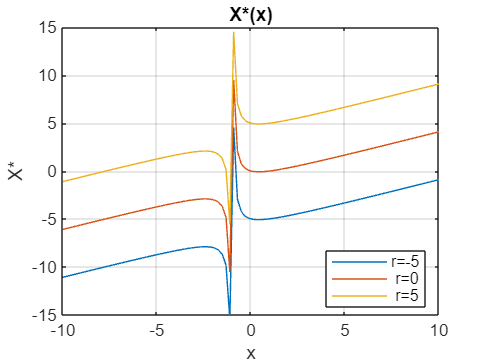


% GRAFICA X*(x) con variantes de r:
r_desde=-5; r_hasta=5; r_paso=5;
r_grafica=r_desde:r_paso:r_hasta; %Asigno valor.
x_desde=-10; x_hasta=10;
x_grafica=linspace(x_desde,x_hasta,100);
for i = 1:length(r_grafica)
    Fsn_grafica=real(subs(subs(Fsn,r,r_grafica(i)),x,x_grafica)); %sustituye r y x por valor numéricos.
    plot(x_grafica,Fsn_grafica); %Grafica Fsn con variantes de r.
    hold on;
end
ylim([-15 15])
grid on
title("X*(x)");
xlabel("x");
ylabel("X*");
% Crear leyenda para indicar valores de r
legendStrings = cellstr(num2str(r_grafica', 'r=%g'));
legend(legendStrings, 'Location', 'best');
hold off;

Para analizar este sistema, se encuentra los PE, linealizando alrededor de estos puntos y se analiza la estabilidad de cada uno.

xss_sn = simplify(solve(Fsn==0,x),"Steps",100) %resuelve eca, despeja X y simplifica hasta 100 pásos.

$$xss\_sn = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-r\\ \frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-r+\frac{1}{2} \end{array}\right)$$

En este caso, tenemos 2 PE. Por lo que se linealiza en estos puntos

Para $x_a =\frac{1}{2}-\sqrt{r^2 -3r+\frac{1}{4}}-r$

Se tiene que el jacobiano de manera reducida $A=\frac{1}{2}-\frac{1}{{\left(\frac{3}{2}-\sqrt{r^2 -3r+\frac{1}{4}}-r\right)}^2 }$, para este caso $\frac{3}{2}-\sqrt{r^2 -3r+\frac{1}{4}}-r\not= 0$, entonces tenemos que el intervalo es $\frac{3+2\sqrt{2}}{2}\ge$$r\le \frac{3-2\sqrt{2}}{2}$ y  el jacobiano existe fuera del intervalo 

Para $x_b =\frac{1}{2}+\sqrt{r^2 -3r+\frac{1}{4}}-r$

Se tiene que el jacobiano de manera reducida $A=\frac{1}{2}-\frac{1}{{\left(\frac{3}{2}+\sqrt{r^2 -3r+\frac{1}{4}}-r\right)}^2 }$, para este caso $\frac{3}{2}+\sqrt{r^2 -3r+\frac{1}{4}}-r\not= 0$, entonces tenemos que el intervalo es $\frac{3+2\sqrt{2}}{2}\ge$$r\le \frac{3-2\sqrt{2}}{2}$ y  el jacobiano existe fuera del intervalo 

A = jacobian(Fsn,x); %Linealiza.

A_a = subs(A,x,xss_sn(1)) % Para el punto de equilibrio 1

$$A\_a = \frac{1}{r+\frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-\frac{3}{2}}-\frac{r+\frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-\frac{1}{2}}{{\left(r+\frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-\frac{3}{2}\right)}^{2}}+\frac{1}{2}$$

A_b = subs(A,x,xss_sn(2)) % Para PE 2, collect agrupa fracción.

$$A\_b = \frac{\frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-r+\frac{1}{2}}{{\left(\frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-r+\frac{3}{2}\right)}^{2}}-\frac{1}{\frac{\sqrt{4\,r^{2}-12\,r+1}}{2}-r+\frac{3}{2}}+\frac{1}{2}$$

%Asigna valor para resolver para ese punto (mas factible) quiero resultado REAL:
r_asignado=5 %Asignamos valor para probar.

r_asignado = 5

A_a_posible=double(subs(A_a,r,r_asignado)) %Sustituye r por valor.

A_a_posible = 0.4777

A_b_posible=double(subs(A_b,r,r_asignado))

A_b_posible = -10.7277

En este caso, para los dos PE se hace el siguiente análisis:

xss_sn_num = double(subs(xss_sn,r,r_asignado))

xss_sn_num =    -7.7016
   -1.2984


disp("Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t")

Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t


## Simulación de la Bifurcación Saddle - Node

Tsim = 40;              % Tiempo de simulación
Ts = 0.1;               % Periodo de muestreo
x0 = -4;                 % Condiciones iniciales Modificarse ++++++++++++++
disp("Condición inicial: "+ x0);

Condición inicial: -4


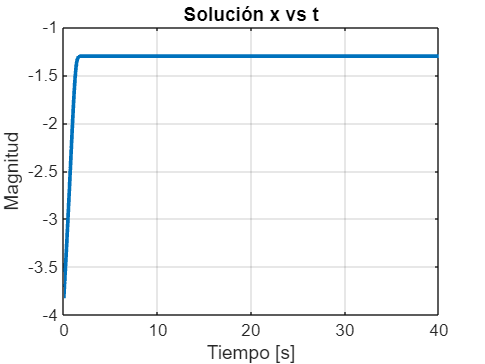

Ns = round(Tsim/Ts);    % Iteraciones
r_sim = linspace(-5,5,Ns); % Debe modificarse+++++++++++++++++++++++
t_sim = linspace(0,Ns*Ts,Ns);

% Solución ED
for i = 1:Ns
    % Simulación de la ED

    [t1,xd] = ode45(@(t,x) saddlenode_314(t,x,r_asignado), [0 Ts], x0); %REVISAR SI DEBE PONERSE R ASIGNADO +++++++++++++++++++
    x0 = xd(end,:)';

    % Análisis de Bifurcación

    fr(:,i) = double(subs(xss_sn,r,r_sim(i)));

    if imag(fr(:,i)) ~= 0
        fr(:,i) = NaN;      % Elimina los valores imaginarios cuando evalúa los posibles valores de r en los PE
    end
 
    % Guardar valores
    x_sim(i) = x0;
end

% Gráficas

figure("Name","Solución del sistema y diagrama de bifurcación")

%subplot(1,2,1)
plot(t_sim,x_sim,LineWidth=2)
xlabel("Tiempo [s]")
ylabel("Magnitud")
title("Solución x vs t")
grid on

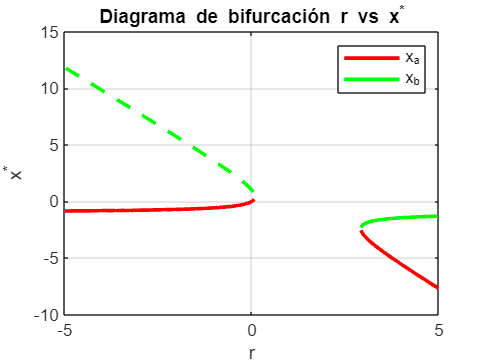


%subplot(1,2,2)
plot(r_sim,real(fr(1,:)),"LineWidth",2,"Color","r")
hold on
plot(r_sim(r_sim <5 & r_sim>2.9), real(fr(2,r_sim <5 & r_sim>2.9)), 'LineWidth', 2, 'Color', 'g')
plot(r_sim(r_sim >-5 & r_sim<0.06), real(fr(2,r_sim >-5 & r_sim<0.06)), 'LineWidth', 2, 'Color', 'g',"LineStyle","--")
%plot(r_sim,real(fr(2,:)),"LineWidth",2,"Color","g","LineStyle","--")
hold off
legend(["x_a" "x_b"])
title("Diagrama de bifurcación r vs x^*")
xlabel("r")
ylabel("x^*")
grid on

#### Bifurcación Saddle - Node

function dxdt = saddlenode_314(t,x,r)
    dxdt = r+1/2*x-x/(1+x);
end